`Erfan Panahi ``810103084`

# `Introduction to Statistical Inference`

## `Homework #02 - ``Problem 13`

clc
clear
close all

- `Part a.`

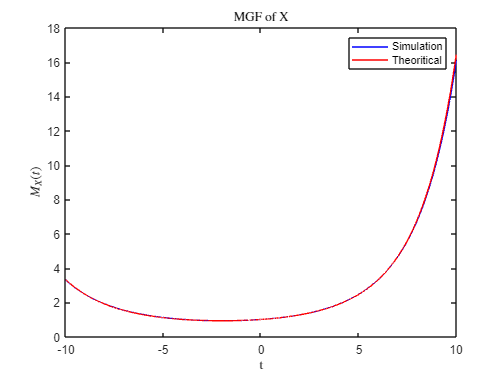

N = 1e4;
T = 10;
dt = 0.001;
mu = 0.08;
sigma = 0.2;
X = sigma * randn(1, N) + mu;
t = -T:dt:T;
M_simulation = MGF(X, t);
M_theoritical = exp(mu * t) .* exp(sigma^2/2 * t.^2);
plot(t, M_simulation, 'b', t, M_theoritical, 'r')
xlabel('t', 'Interpreter','latex');
ylabel('$M_X(t)$', 'Interpreter','latex');
title('MGF of X', 'Interpreter','latex');
legend('Simulation', 'Theoritical')

- `Part b.`

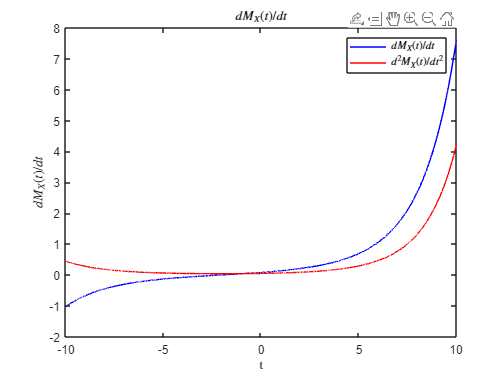

dM_sim = diff(M_simulation) / dt;
d2M_sim = diff(dM_sim) / dt;
plot(t(2:end), dM_sim, 'b', t(3:end), d2M_sim, 'r')
xlabel('t', 'Interpreter','latex');
ylabel('$dM_X(t)/dt$', 'Interpreter','latex');
title('$dM_X(t)/dt$', 'Interpreter','latex');
legend('$dM_X(t)/dt$', '$d^2M_X(t)/dt^2$', 'Interpreter','latex')

index0 = find(t == 0);
E_X = dM_sim(index0 + 1)

E_X = 0.0798

E_X2 = d2M_sim(index0 + 2);
var_X = E_X2 - E_X^2

var_X = 0.0406

- `Part c.`

d3M_sim = diff(d2M_sim) / dt;
E_X3 = d3M_sim(index0 + 3)

E_X3 = 0.0102

skewness_X = (E_X3 - 3 * E_X * E_X2 + 3 * (E_X)^2 * E_X2 - (E_X)^3) / (var_X)^1.5

skewness_X = -0.0821

# `Functions.`

function [M] = MGF(X, t)
    M = mean(exp(X.' * t));
end